# Laboratory1 : Forward Kinematics of a Spherical Manipulator

## Objective:

    to solve and to create the Denavit Hartenberg Matrix to simplify the following Transformation of the Mechanical Manipulator (In this case, Spherical Manipulator)

## Algorithm:

    1. Identify the Link Length

    2. Create a Denavit Hartenberg Paramteric Table

    3. Plug-in the Matrix of the following Manipulator

    4. Matrix Multiply the Transformation Matrices.

## Conventions Used:

    a_<number> - Constant Link Length

    theta = Joint Offset

    alpha = Link Twist

    r = Link Length

    d = Link Offset

### Display the Lengths

% Clear All Defined Variables

clear all;
clc;

disp("Spherical Manipulator")

Spherical Manipulator



syms a1 a2 a3

% Link Lengths a1 to a3

a1 = 20; %20mm
a2 = 15; %15mm
a3 = 15; %15mm

### Defining the DH Parameters

In, Python, we tend to compute the Matrix of it based on the specific angles given. Since in Reality, Mechanical Manipulators tend not to work on this way. We must program a mathematical model of machanical manipulators to visualize the movement itself.

% Take note of theta, alpha, r/a, and d
H_01 = Revolute('alpha', pi/2, 'd', a1)

 
H_01 = 
Revolute(std): theta=q, d=20, a=0, alpha=1.5708, offset=0


H_12 = Revolute('alpha', pi/2, 'offset', pi/2)

 
H_12 = 
Revolute(std): theta=q, d=0, a=0, alpha=1.5708, offset=1.5708


H_23 = Prismatic('offset', a2 + a3)

 
H_23 = 
Prismatic(std): theta=0, d=q, a=0, alpha=0, offset=30



%Defining the Joint Limits (IRL it has following limits of course)

H_01.qlim = pi/180 * [-90, 90];
H_12.qlim = pi/180 * [-90, 90];
H_23.qlim = [0, 50];

### Combining the DH Parameters into a `SerialLink` object

Once created the following DH Parameters, we can connect using a SerialLink object. This displays the DH Parametric Table we've discussed in Robotics 1

Spherical = SerialLink([H_01, H_12,H_23], 'name', 'Spherical Manipulator')

 
Spherical = 
 
Spherical Manipulator:: 3 axis, RRP, stdDH, slowRNE              
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|         20|          0|     1.5708|          0|
|  2|         q2|          0|          0|     1.5708|     1.5708|
|  3|          0|         q3|          0|          0|         30|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Plotting and Teaching the Robot

Once done, we are about to plot the robot in the origin, and teach the robot (Have Sliders to know the position of the end effector based on the jont angles)

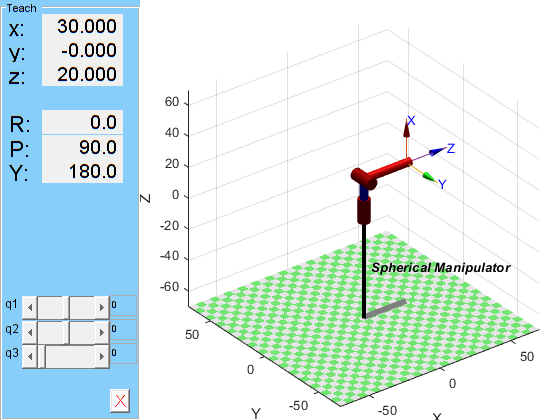

origin = [0 0 0];
workspace = [-25,25,-25,25,-10,25];
Spherical.plot(origin);
Spherical.teach();